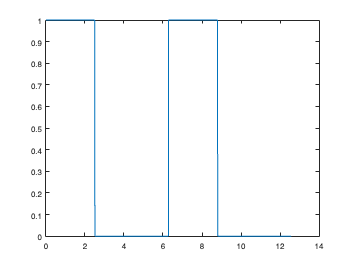

T = 2 * pi;
duty_cycle = 40;

x = 0:0.01:4*pi;
y = (square(x, duty_cycle) + 1) .* 0.5;

plot(x, y)




n = [1:100]';
t = x;
A = 1;
tau = T-(T .* duty_cycle ./ 100)

tau = 3.7699

omega = (2 .* pi) ./ T;

A0 = A .* (1 - (tau./T))

A0 = 0.4000

An = (A ./ (n .* pi)) .* (sin(-tau.*n.*omega)-sin(-(T./2).*n.*omega)+sin(n.*omega.*(T./2)));
Bn = (-A ./ (n .* pi)) .* (cos(-n .* omega .* tau)-cos(-n .* omega .* (T./2))+cos(n .* omega .* (T./2))-1); % !!!!

partial = [An .* cos(n .* omega .* x) + Bn .* sin(n .* omega .* t)]'

partial =     0.1871   -0.1514    0.1009   -0.0468    0.0000    0.0312   -0.0432    0.0378   -0.0208   -0.0000    0.0170   -0.0252    0.0233   -0.0134    0.0000    0.0117   -0.0178    0.0168   -0.0098   -0.0000    0.0089   -0.0138    0.0132   -0.0078    0.0000    0.0072   -0.0112    0.0108   -0.0065   -0.0000    0.0060   -0.0095    0.0092   -0.0055    0.0000    0.0052   -0.0082    0.0080   -0.0048   -0.0000    0.0046   -0.0072    0.0070   -0.0043    0.0000    0.0041   -0.0064    0.0063   -0.0038    0.0000
    0.1928   -0.1491    0.1031   -0.0410    0.0000    0.0369   -0.0409    0.0399   -0.0150   -0.0000    0.0227   -0.0229    0.0253   -0.0075    0.0000    0.0173   -0.0154    0.0187   -0.0039   -0.0000    0.0144   -0.0112    0.0150   -0.0019    0.0000    0.0126   -0.0086    0.0126   -0.0005   -0.0000    0.0114   -0.0068    0.0108    0.0005    0.0000    0.0105   -0.0055    0.0095    0.0012   -0.0000    0.0098   -0.0044    0.0085    0.0017    0.0000    0.0092   -0.0036    0.0077    0.002

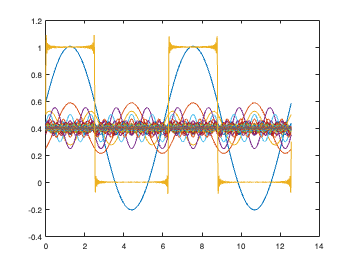

final   = sum(partial, 2);

plot(x, partial + A0, x, final + A0);